##   Save Video

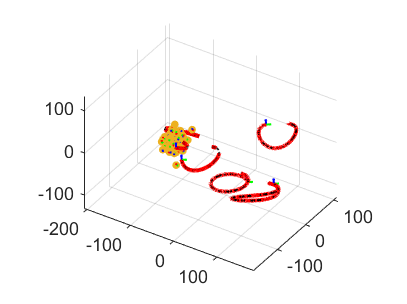

if(1)
load('save_video_helper/data/data.mat');
figure();
plist=positions(1).pos;
len=size(plist,1);

n=5;



for i=1:n
    real_path=real_path_all(i).rp;
   
    sz_RealPath=length(real_path); 
    real_p_imu=zeros(sz_RealPath,3);
    for m=1:sz_RealPath
        real_p_imu(m,:)=real_path(m).T(1:3,4)';
    end

   p= plot3(real_p_imu(:,1), real_p_imu(:,2), real_p_imu(:,3),'LineWidth',1,'DisplayName','Ground Truth','color','black'); hold on   
    p.LineStyle = '-.';
end
nnn=1;
Eff_Range=90;
% 把landmarks也画下来
num_lm = length(landmarks);
p_lm_list = zeros(num_lm,3);
for i = 1:num_lm

    pos_now(i,:) = landmarks(i).T(1:3,4)';
   
    dot=scatter3(pos_now(i,1), pos_now(i,2),pos_now(i,3),15,'o','filled','MarkerFaceColor',[0.9290 0.6940 0.1250]); hold on
    
    R=  landmarks(i).T(1:3,1:3);
    

    axx=[1;0;0];axy=[0;1;0];axz=[0;0;1];
    bx=R*axx;
    by=R*axy;
    bz=R*axz;

       xx= quiver3(pos_now(i,1),pos_now(i,2),pos_now(i,3), bx(1), bx(2),bx(3)  ,4 );hold on
       xx.Color='red';
        xx.MaxHeadSize=4;

        yy=quiver3(pos_now(i,1),pos_now(i,2),pos_now(i,3), by(1), by(2),by(3)    ,4);hold on
        zz=quiver3(pos_now(i,1),pos_now(i,2),pos_now(i,3), bz(1), bz(2),bz(3)    ,4); hold on
        yy.Color='green';
        zz.Color='blue';
        yy.MaxHeadSize=4;
      
        zz.MaxHeadSize=4;


        xx.LineWidth=1;
        yy.LineWidth=1;
        zz.LineWidth=1;
        hold on


% 
%     p_lm_list(j,:) = landmarks(j).T(1:3,4)';
%     scatter3(p_lm_list(j,1), p_lm_list(j,2),p_lm_list(j,3),'.','green'); hold on

end
axis equal
view([-22 35])
f2=gca;

xlim([-205 185])
ylim([-187 109])
zlim([-131 135])
view([-16 36])
grid on

view([-327 35]);hold on

% 


for i=1:len-1

    if (i>=2)
        for zzz=1:5
        delete(xx(zzz));
        delete(yy(zzz));
        delete(zz(zzz));
        end
       
    end  
    for num=1:5 %每次要把五个机器人都画出来        
         robotnow=method3(num).X;
        pos_now=positions(num).pos;
        plot3([pos_now(i,1),pos_now(i+1,1)], [pos_now(i,2),pos_now(i+1,2)],[pos_now(i,3),pos_now(i+1,3)],'LineWidth',2,'color','red');
        R=robotnow(i).Rimu;

        axx=[1;0;0];axy=[0;1;0];axz=[0;0;1];
        bx=R*axx;
        by=R*axy;
        bz=R*axz;

       xx(num)= quiver3(pos_now(i,1),pos_now(i,2),pos_now(i,3), bx(1), bx(2),bx(3)  ,10 );hold on
       xx(num).Color='red';
        xx(num).MaxHeadSize=6;

        yy(num)=quiver3(pos_now(i,1),pos_now(i,2),pos_now(i,3), by(1), by(2),by(3)    ,10);hold on
        zz(num)=quiver3(pos_now(i,1),pos_now(i,2),pos_now(i,3), bz(1), bz(2),bz(3)    ,10); hold on
        yy(num).Color='green';
        zz(num).Color='blue';
        yy(num).MaxHeadSize=6;
      
        zz(num).MaxHeadSize=6;


        xx(num).LineWidth=1;
        yy(num).LineWidth=1;
        zz(num).LineWidth=1;
        hold on
       

    end
    
     M(nnn)=getframe(gcf); 
    nnn=nnn+1;
%     pause(0.001);
end
save('save_video_helper/data/multi_d18.mat','M')
end


figure
movie(gcf,M,1) 


movie1=VideoWriter('save_video_helper/data/multi_d18','MPEG-4');
movie1.FrameRate=20;
open(movie1);
writeVideo(movie1,M);
close(movie1)

